IBB_st.name='IBB'; 
IBB_st.lat=34.3405;
IBB_st.lon=-111.683;
IBB_st.alt=1297;

IBB_rd=read_betsy('ike_head',IBB_st.name);

datevec(IBB_rd.Time(1))

ans =         2001           4           2           0           0           0

datevec(IBB_rd.Time(end))

ans =         2010           7           1           0           0           0

prctile(IBB_rd.U_S,[5, 50, 95])

ans =    11.3015   28.5100   79.5160

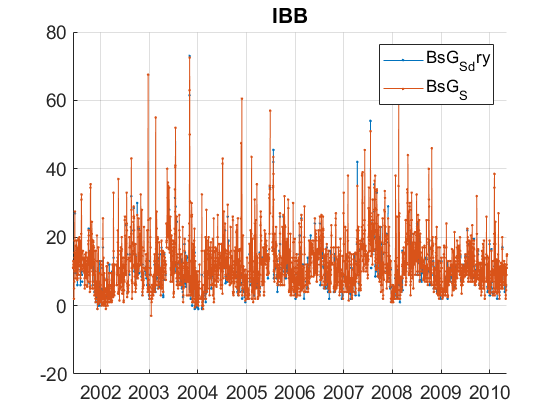

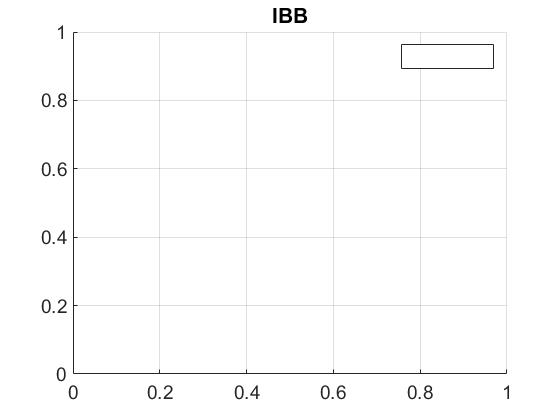

plotFigControl(IBB_rd,IBB_st.name);

% 1 size cut, 
% sc: ok, clear seasonal cycle, max in summer-autumn, some negatives

% lambdaSC=[450;550;700]*ones(1,4);
% lambdaAE3=[467;530;660]*ones(1,4);
% lambdaAE7=[370 470 520 590 660 880 950];
% IBB_cal=compute_exp_SSA(IBB_rd,lambdaSC, lambdaAE3);
% plotFigControl_cal(IBB_cal, IBB_st.name);

%Questions:
%problems:
% hole from end 2009 to April 2016

IBB_t=timetable(IBB_rd.Time);
% begin at the beginning of a year:2002
%end year: 2009 --> 7y too short


